# Calculate Optical Properties from MODIS data using Gauss-Newton

# Compare This With VOCALS-REx in-situ Measurements

Using the first 7 MODIS bands, this code will estimate a vertical droplet profile.

The code assumes a droplet profile shape: adiabatic, sub-adiabatic, etc.

The code uses the TBLUT method to estimate $r_e
$ and $\tau_c^\lambda$ which will be used as the initial guess in the Gauss-Newton iterative solution

Load a data set. The code will first run the TBLUT method to estimate $r_e
$ and $\tau_c^\lambda$. Then the code will step through the procedure for solving the nonlinear Gauss-Newton method in a pedagogical way.

By Andrew John Buggee

% add libRadTran libraries to the matlab path
addLibRadTran_paths;
scriptPlotting_wht;

## Load MODIS data

% Load modis data and create input structure
clear variables

% Determine which computer you're using
computer_name = whatComputer;

% Find the folder where the mie calculations are stored
% find the folder where the water cloud files are stored.
if strcmp(computer_name,'anbu8374')==true

    % -----------------------------------------
    % ------ Folders on my Mac Desktop --------
    % -----------------------------------------

    % Define the MODIS folder name

    % ----- November 9th at decimal time 0.611 (14:40) -----
    %modisFolder = '/Users/anbu8374/Documents/MATLAB/HyperSpectral_Cloud_Retrieval/MODIS_Cloud_Retrieval/MODIS_data/2008_11_09/';


    % ----- November 11th at decimal time 0.604 (14:30) -----
    %modisFolder = ['/Users/anbu8374/Documents/MATLAB/HyperSpectral_Cloud_Retrieval/MODIS_Cloud_Retrieval/MODIS_data/2008_11_11_1430/'];


    % ----- November 11th at decimal time 0.784 (18:50) -----
    modisFolder = '/Users/anbu8374/Documents/MATLAB/HyperSpectral_Cloud_Retrieval/MODIS_Cloud_Retrieval/MODIS_data/2008_11_11_1850/';

    % ----------------------------------------
    % ***** Define the VOCALS-REx Folder *****
    % ----------------------------------------

    % ----- November 9th data -----
%     vocalsRexFolder = '/Users/anbu8374/Documents/MATLAB/HyperSpectral_Cloud_Retrieval/VOCALS_REx/2008_11_09/';
%     vocalsRexFile = 'RF11.20081109.125700_213600.PNI.nc';



    % ----- November 11 data -----
    vocalsRexFolder = '/Users/anbu8374/Documents/MATLAB/HyperSpectral_Cloud_Retrieval/VOCALS_REx/2008_11_11/';
    vocalsRexFile = 'RF12.20081111.125000_214500.PNI.nc';

elseif strcmp(computer_name,'andrewbuggee')==true

    % -------------------------------------
    % ------ Folders on my Macbook --------
    % -------------------------------------

    % Define the MODIS folder name

    % -- February 5th data overlaps with AVIRIS ---
    %     modisFolder = ['/Users/andrewbuggee/Documents/MATLAB/CU Boulder/Hyperspectral_Cloud_Retrievals/',...
    %         'MODIS_Cloud_Retrieval/MODIS_data/2015_02_05/'];

    modisFolder = ['/Users/andrewbuggee/Documents/MATLAB/CU Boulder/Hyperspectral_Cloud_Retrievals/',...
        'MODIS_Cloud_Retrieval/MODIS_data/2021_07_13/'];

    %     modisFolder = ['/Users/andrewbuggee/Documents/MATLAB/CU Boulder/Hyperspectral_Cloud_Retrievals/',...
    %         'MODIS_Cloud_Retrieval/MODIS_data/2022_05_22/'];

    % Define the AVIRIS foldername
    vocalsRexFolder = ['/Users/andrewbuggee/Documents/MATLAB/CU Boulder/Hyperspectral_Cloud_Retrievals/',...
        'AVIRIS/AVIRIS-Classic-data/2_5_2015/UTC_21_10/orthorectified_radiance/'];

end




[modis,L1B_fileName] = retrieveMODIS_data(modisFolder);

% ----- Create a structure defining inputs of the problem -----

modisInputs = create_modis_inputs(modisFolder, L1B_fileName);

## Plot MODIS Estimates for Re and Tau with uncertainty

%f = plot_R16_and_R17_withUnertainty(modis, modisInputs);

% plot the effective radius and the optical depth for bands 1 and 7
%f = plot_R17_and_T17_withUnertainty(modis, modisInputs);


## Load the VOCALS-REx Data

% ---------------------------------------------------------------------
% ------------ Do you want to load VOCALS-REx data? -----------------------
% ---------------------------------------------------------------------


loadVOCALSdata = true;

% ---------------------------------------------------------------------
% ----------- Do you want to use VOCALS-REx pixels? -----------------------
% ---------------------------------------------------------------------

% If flag below is true, only suitable pixels within the AVIRIS data set
% will be used
useVOCALS_pixelLocations = true;



if loadVOCALSdata==true
    vocalsRex = readVocalsRex([vocalsRexFolder,vocalsRexFile]);

end

% ------------------------------------------------
% ----- We dont need all of this data ------------
% ------------------------------------------------

% Lets only keep the vocalsRex data we need
% Time is measured in seconds since the startTime

vocalsRex = cropVocalsRex2MODIS(vocalsRex,modis,vocalsRexFolder,modisFolder);



## Plot this data overlapping MODIS

% figure; geoscatter(modis.geo.lat(:), modis.geo.long(:), 10, reshape(modis.EV1km.reflectance(:,:,1),[],1),'.');
% cb = colorbar;
% set(get(cb, 'label'), 'string', 'Reflectance $(1/sr)$','Interpreter','latex', 'Fontsize',22)
% set(gca, 'FontSize',25)
% set(gca, 'FontWeight', 'bold')
% set(gcf, 'Position', [0 0 1000 700])
% title('Reflectance $650 \; nm$ band','Interpreter','latex', 'FontSize', 40)
% hold on
% geoscatter(vocalsRex.latitude, vocalsRex.longitude, 10, "red",'*')
% geolimits([min(vocalsRex.latitude)-5 max(vocalsRex.latitude)+5],[min(vocalsRex.longitude)-5 max(vocalsRex.longitude)+5])




## Show the VOCALS-REx Droplet Size Estimate along with the MODIS estimate

% ------------------------------------------------------------------
% ------------------ Compute optical depth -------------------------
% ------------------------------------------------------------------
% optical depth is defined to be 0 at cloud top and increasing towards
% cloud bottom
vector_length = length(vocalsRex.altitude);
tau = zeros(1,vector_length-1);
for ii = 1:vector_length-1
    
    % we have to convert Nc and re to have the same units as the alitude,
    % which is in meters
    re_meters = vocalsRex.re(vector_length-ii:vector_length)./1e6;                                   % meters
    total_Nc_meters = vocalsRex.total_Nc(vector_length-ii:vector_length).*1e6;                           % #/m^3
    altitude = vocalsRex.altitude(end) -  vocalsRex.altitude(vector_length-ii:vector_length);
    % we need to flip these vectors so we start integratin at the cloud
    % top!
    tau(ii) = 2*pi* trapz(fliplr(altitude), fliplr(re_meters.^2 .* total_Nc_meters));

end

% add a zero at the begining!
tau = [0,tau];


% ------------------------------------------------------------------
% ---------------- Compute Liquid Water Path -----------------------
% ------------------------------------------------------------------

LWP = trapz(vocalsRex.altitude, vocalsRex.lwc);                 % grams of water/m^2



% I want a subplot with the number concentration and altitude, and the
% effective radius with altitude
nice_blue = [0 0.4470 0.741];
nice_orange = [0.8500, 0.3250, 0.0980];

figure;
plot(fliplr(vocalsRex.re),tau,'k'); 
set(gca,'YDir','reverse')
ylabel('$\tau$','interpreter','latex','FontSize',35); 
xlabel('$r_{e}$ $$(\mu m)$$','Interpreter','latex')
title('Comparison between in-situ and MODIS retrieved $r_e$', 'Interpreter','latex')
grid on; grid minor; hold on; 

% Fit a curve to the in-situ data to show the capability we are interested
% in devloping

curve_fit_linewidth = 6;
curve_fit_color = mySavedColors(1,'fixed');                        % Bright pink

f = fit(tau', fliplr(vocalsRex.re)', 'smoothingspline','SmoothingParam',0.9);

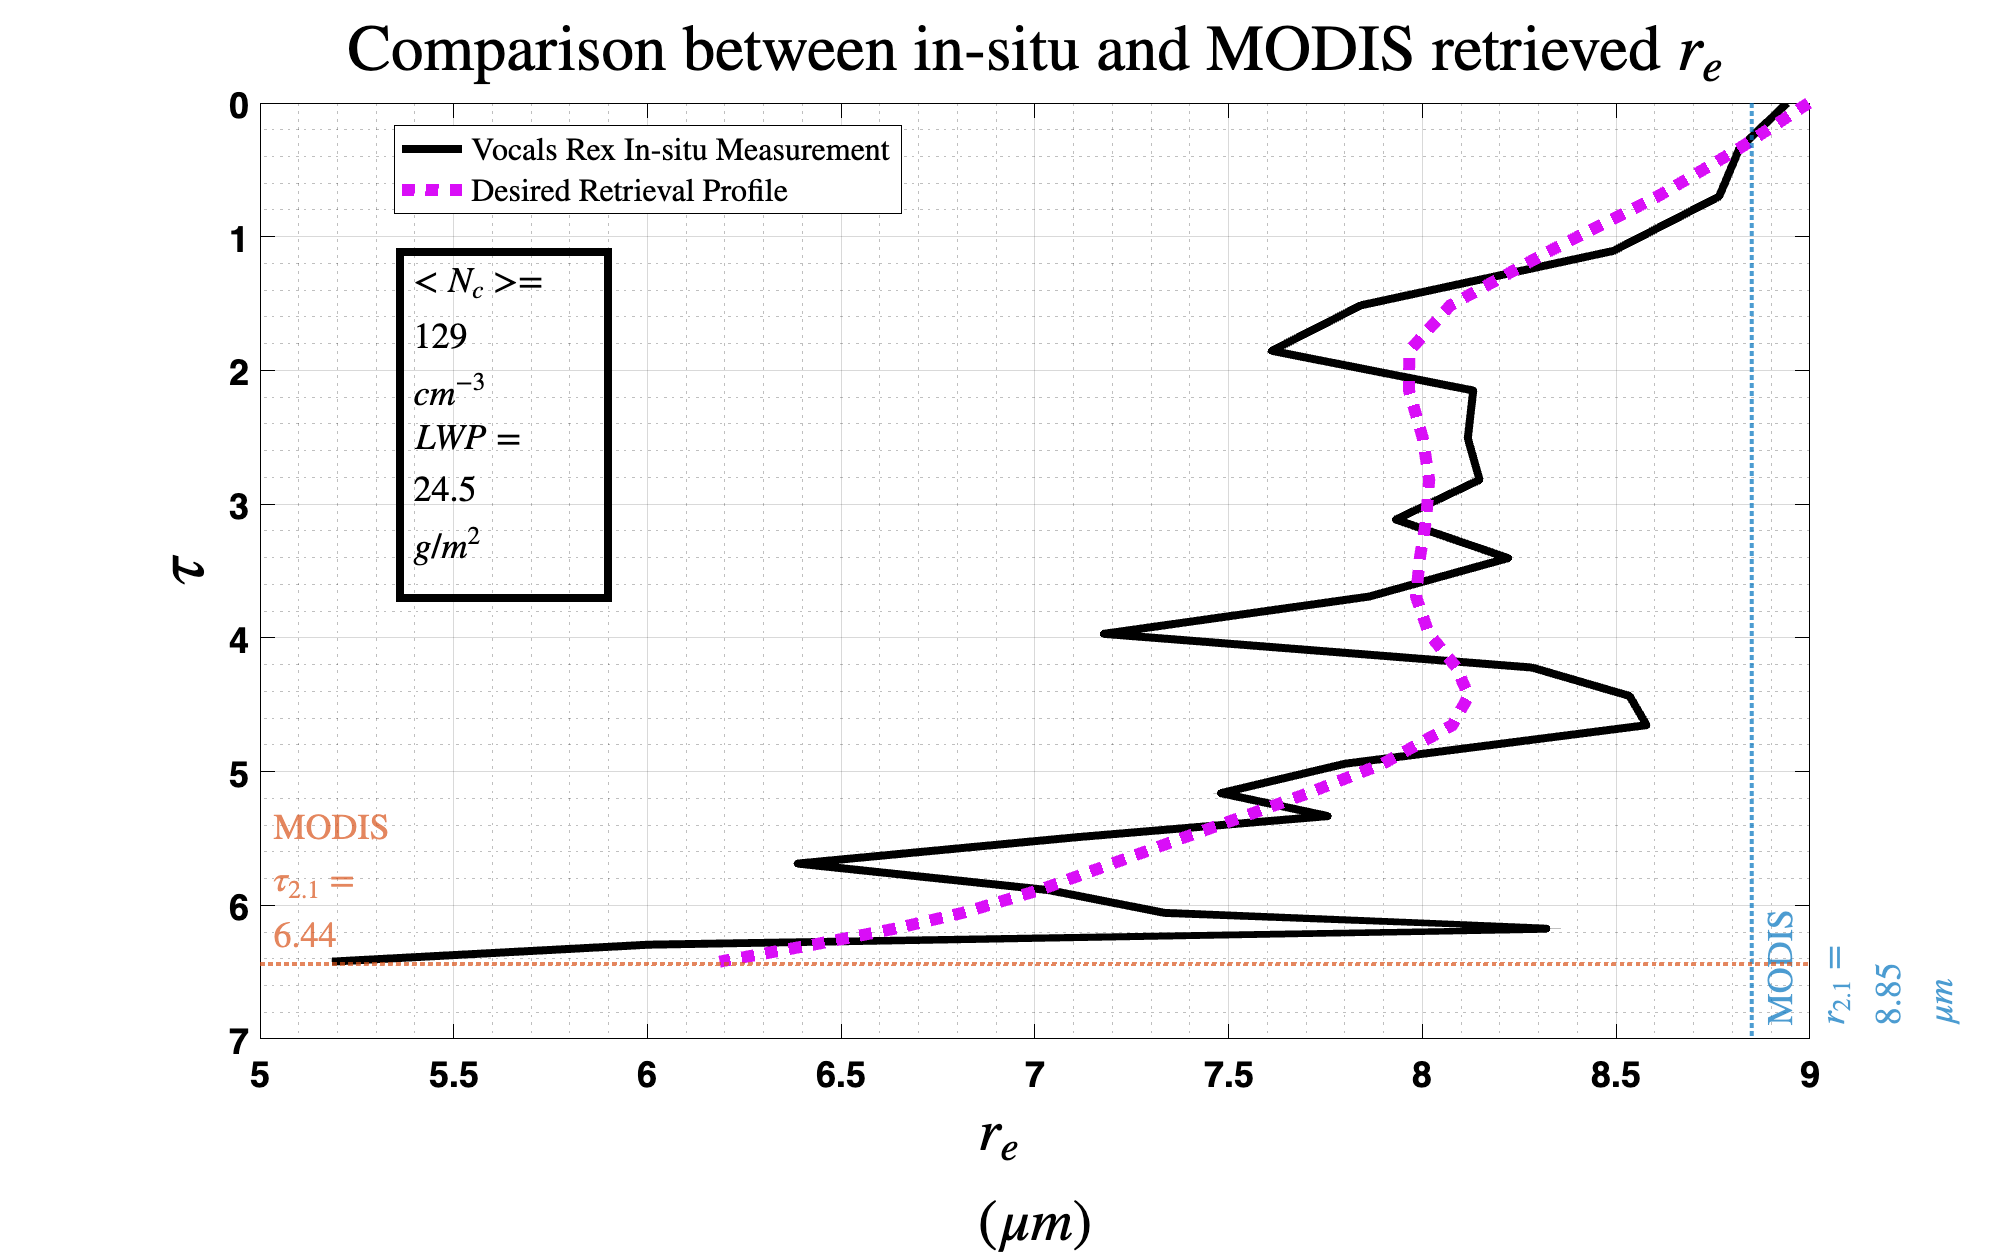

hold on;
plot(f(tau),tau,'Color',curve_fit_color,'LineStyle',':', 'LineWidth',curve_fit_linewidth);

% Plot the z-space in meters on the right axis
yyaxis right
ylim([0, vocalsRex.altitude(end) - vocalsRex.altitude(1)])
set(gca,'YColor','black')
ylabel('Altitude within cloud $(m)$', 'Interpreter','latex','FontSize',30); 
yyaxis left

% Label cloud top and cloud bottom
% Create textbox
annotation('textbox',[0.029,0.865079365079366,0.051,0.077777777777778],...
    'String',{'Cloud','Top'},...
    'LineStyle','none',...
    'Interpreter','latex',...
    'FontSize',22,...
    'FitBoxToText','off');

% Create textbox
annotation('textbox',[0.029,0.096825396825397,0.051,0.077777777777778],...
    'String',{'Cloud','Bottom'},...
    'LineStyle','none',...
    'Interpreter','latex',...
    'FontSize',22,...
    'FitBoxToText','off');



% Plot the modis droplet estimate as a constant vertical line
xl0 = xline(modis.cloud.effRadius17(vocalsRex.modisIndex_minDist),':',['MODIS $$r_{2.1} = $$',num2str(modis.cloud.effRadius17(vocalsRex.modisIndex_minDist)), '$$\mu m$$'], 'Fontsize',18, 'Interpreter','latex','LineWidth',2,'Color',nice_blue);
xl0.LabelVerticalAlignment = 'bottom';

% Plot the MODIS optical depth estiamte as a constant horizontal line
yl0 = yline(modis.cloud.optThickness17(vocalsRex.modisIndex_minDist),':',['MODIS $$\tau_{2.1} = $$',num2str(modis.cloud.optThickness17(vocalsRex.modisIndex_minDist))], 'Fontsize',18, 'Interpreter','latex','LineWidth',2,'Color',nice_orange);
yl0.LabelVerticalAlignment = 'top';
yl0.LabelHorizontalAlignment = 'left';


% Let's compute the mean number concentration within this cloud and print
% it on our plot

mean_Nc = mean(vocalsRex.total_Nc);

dim = [.2 .5 .3 .3];
str = ['$$< N_c > = \;$$',num2str(round(mean_Nc)),' $$cm^{-3}$$',newline,'$$LWP = $$',num2str(round(LWP,1)),' $$g/m^{2}$$'];
annotation('textbox',dim,'String',str,'FitBoxToText','on','Interpreter','latex','FontSize',18,'FontWeight','bold');
set(gcf,'Position',[0 0 1000 630])

% Create a Legend with only the two black curves
legend('Vocals Rex In-situ Measurement', 'Desired Retrieval Profile', 'Interpreter','latex', 'Location','best')

## Plot the VOCALS-REx Position data on top of the MODIS data

% if loadVOCALSdata==true
%     f = plot_MODIS_re_and_Tau_with_VOCALS_overlap(modis,modisInputs, vocalsRex);
% 
% end

## Find or Load Pixels for the TBLUT Retrieval

% There may be a time delay, lets subtract a minute from the index found
% above
bufferTime = 0;

% Find the MODIS pixels that overlap with VOCALS-REx

pixels2use = find_MODIS_VOCALS_overlapping_pixels(modis, modisInputs, vocalsRex);


% Tell MODIS_INPUTS to use only these pixels found
modisInputs.pixels.num_2calculate = length(pixels2use.res1km.linearIndex);

## Plot the In-Situ Measurements with the MODIS Retrieval


% indicating a cloud! The last measurement occurs at time = 6278 indicating
% the end of the cloud.
% grab the data after time = 6227 seconds and before time = 6278

%index = vocalsRex.time>6195 & vocalsRex.time<=6256;
%index_PD = vocalsRex.time>= 6241 & vocalsRex.time<=6249;


% f = figure; plot(vocalsRex.re(index), vocalsRex.altitude(index))
% hold on; grid on; grid minor
% xline(modis.cloud.effRadius17(pixels2use.res1km.linearIndex(1)),'r--', 'LineWidth', 5)
% legend('VOCALS-REx','MODIS TBLUT Retrieval','Interpreter','latex','location','best')
% title('In-Situ Measured $r_e$', 'Interpreter','latex')
% xlabel('Effective Radius ($\mu m$)','Interpreter','latex')
% ylabel('Altitude ($m$)','Interpreter','latex')
% set(f,"Position", [0 0 1000, 400])


## Plot the measured reflectance for the pixels being used


% Show the reflectance for bands 1 and 7

% f = figure;
% 
% for ii = 1:length(pixels2use.res1km.linearIndex)
%     subplot(1,2,1)
%     index_row = pixels2use.res1km.row(ii);
%     index_col = pixels2use.res1km.col(ii);
%     plot(modis.cloud.optThickness17(index_row,index_col),modis.EV1km.reflectance(index_row, index_col,1),'.')
%     hold on
%     subplot(1,2,2)
%     plot(modis.cloud.effRadius17(index_row,index_col),modis.EV1km.reflectance(index_row, index_col,7),'.')
%     hold on
% end
% subplot(1,2,1)
% title('Reflectance 650 \mum band')
% xlabel('MODIS \tau_{c} estimate');
% ylabel('Reflectance');
% grid on; grid minor
% subplot(1,2,2)
% title('Reflectance 2130 \mum band')
% xlabel('MODIS r_{e} estimate');
% ylabel('Reflectance');
% grid on; grid minor
% set(f, 'Position', [0 0 1000 500])

## Show MODIS Pixels Within AVIRIS Scene, if Applicable


% if loadVOCALSdata==true && useVOCALS_pixelLocations==true
%     f = plot_MODIS_re_and_Tau_showingAVIRIS_pixels_found(modis,modisInputs, vocalsRex, pixels2use);
% else
%     f = plot_MODIS_reflectance_andPixels2use(modis,pixels2use);
% 
% end



## Create .INP files for MODIS Geometry


if modisInputs.flags.writeINPfiles == true
    % which pixels on the MODIS array are we using for the gemoetry of the
    % problem? The pixels that we found to be suitable!

    names.inp = write_INP_file_4MODIS_homogenous(modisInputs,pixels2use,modis);

    % now lets write the output names

    names.out = writeOutputNames(names.inp);
else

    % if the files already exist, just grab the names!
    names.inp = getMODIS_INPnames_withClouds(modis.solar,modisInputs,pixels2use);
    names.out = writeOutputNames(names.inp);
end


## Run uvspec and calculate Reflectance Function for Model


% geometry stays the same, but we calculate the radiative transfer equation
% for different cloud values (tau,re)

if modisInputs.flags.runUVSPEC == true

    % 1st output - R is the reflectance integrated over a bandwidth
    % 2nd output - Rl is the reflectance at each spectral bin
    tic
    [R,~] = runReflectanceFunction(modisInputs,names);
    toc

elseif modisInputs.flags.runUVSPEC == false

    load('uvspec_CALCS_23-Nov-2021.mat','modisInputs','R');

end


ans =

     1     1     1     1


ans =

     1     2     1     1


ans =

     1     2     2     1


ans =

     1     2     3     1


ans =

     1     2     4     1


ans =

     1     2     5     1


ans =

     1     2     6     1


ans =

     1     2     7     1


ans =

     1     2     8     1


ans =

     1     2     9     1


ans =

     1     3     1     1


ans =

     1     4     1     1


ans =

     1     4     2     1


ans =

     1     4     3     1


ans =

     1     4     4     1


ans =

     1     4     5     1


ans =

     1     4     6     1


ans =

     1     4     7     1


ans =

     1     4     8     1


ans =

     1     4     9     1


ans =

     1     5     1     1


ans =

     1     6     1     1


ans =

     1     1     2     1


ans =

     1     1     3     1


ans =

     1     1     4     1


ans =

     1     1     5     1


ans =

     1     1     6     1


ans =

     1     1     7     1


ans =

     1     1     8     1


ans =

     1

Elapsed time is 134.770965 seconds.



% We want to grab modis reflectances at 1km!!

modisR = grab_modis_reflectance(modis,modisInputs);

%% ----- Compare Reflectance Fucntion of MODIS with Theoretical Calculations (Grid Search) -----

% first grid search is on a coarse grid
% we want to minimize two the reflectance for two wavelengths

% if interpGridScalFactor is 10, then 9 rows will be interpolated to be 90
% rows, and 10 columns will be interpolated to be 100 columns

minVals = leastSquaresGridSearch(modisR, R, modisInputs, pixels2use);

[truth_estimate_table] = gatherTruthEstimateVals(modis, minVals, modisInputs, pixels2use); % containts truth ad estimates and difference

## PLOT THE TBLUT RETRIEVAL RESULTS


% % plot relfectance curves with lines of constant radius
% % if there are more than 3 pixels, this function will plot three random
% % pixels from the set
% f = plotReflectanceCurves_singleBand(R,modisInputs,pixels2use);
% set(f, 'Position', [0 0 1500 600])
% 
% % plot reflectance contours where x and y are tau and r
% 
% %f = plotReflectanceContours(R,inputs,pixels2use);
% %set(f, 'Position', [0 0 1000 400])
% 
% % Plot MODIS re values against my calculated re values
% 
% plot_effRadius_modis_estimates(truth_estimate_table);
% 
% plot_tau_modis_estimates(truth_estimate_table)



## Create Bayes Inputs

% We use the estimates calcualted by the TBLUT as our a priori
GN_inputs = create_bayes_inputs(modisInputs);
disp('Dont forget to check the inputs and change if needed!!')

Dont forget to check the inputs and change if needed!!


## Create Model Prior and Covariance and Measurement Covariance

% I don't need anything but the covariance matrix and the expected values
%inputs = create_model_prior(inputs,data_inputs);


% do you want to use your estimates or the MODIS estimate?

use_MODIS_estimates = true;

GN_inputs = create_model_prior_and_covariance(GN_inputs,truth_estimate_table, use_MODIS_estimates);
GN_inputs = create_MODIS_measurement_covariance(GN_inputs, modis, modisInputs, pixels2use);


## Calculate Retrieval Parameters using Gauss-Newton Method

(iteration,pixel): (1,1)


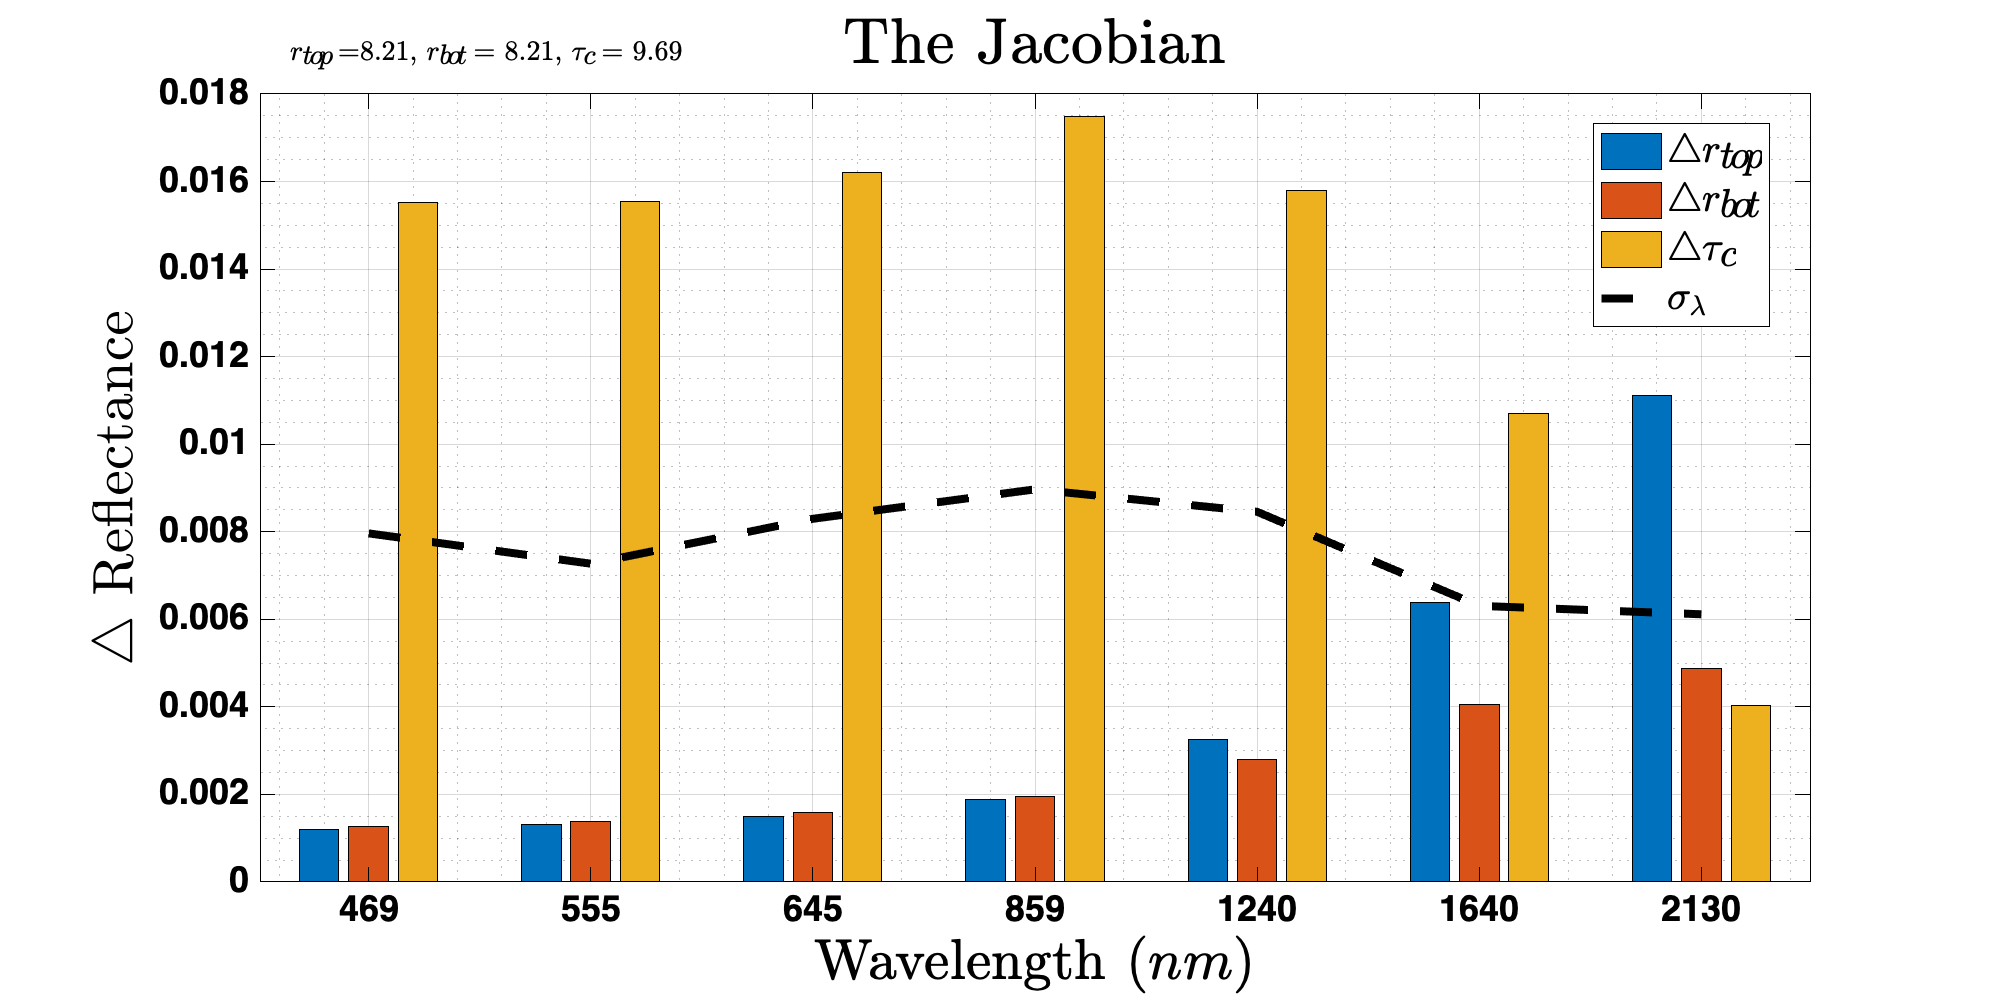


r_bottom = 0.49128. Set to 2.6 \mum
(iteration,pixel): (2,1)


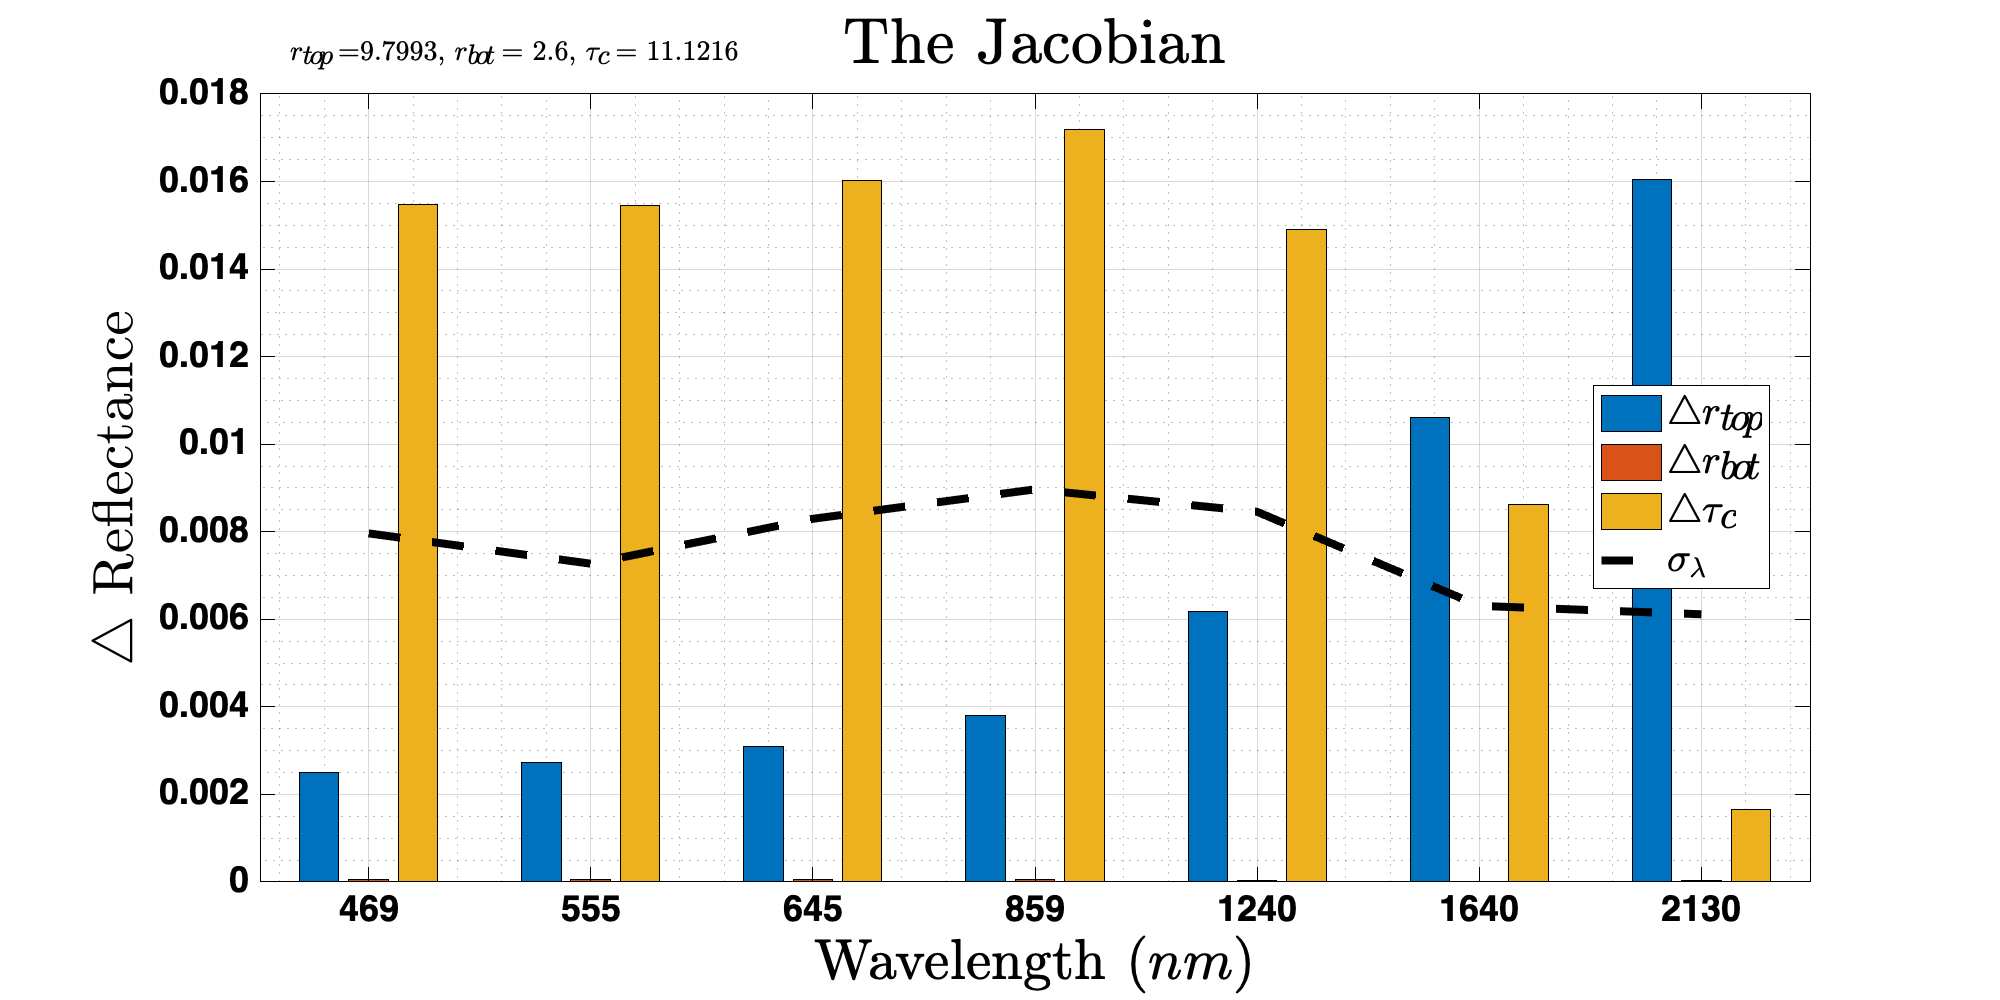

(iteration,pixel): (3,1)


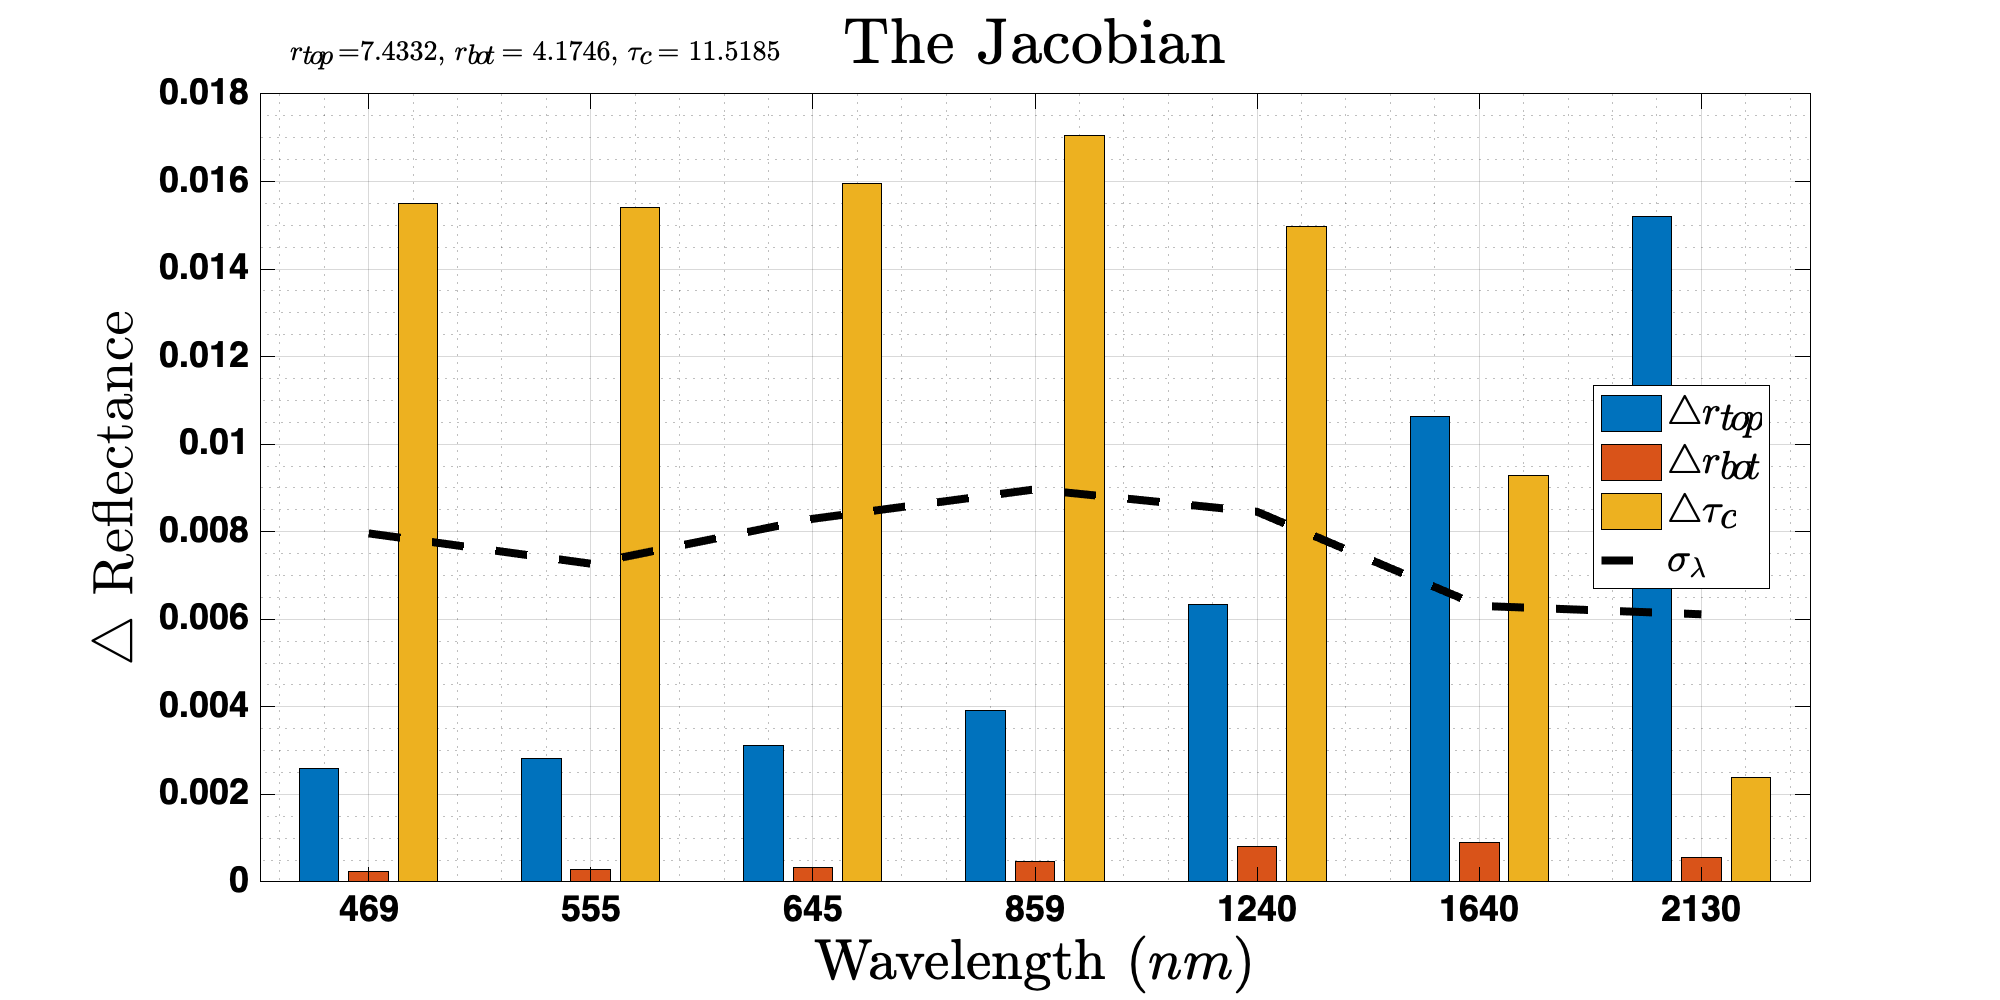

(iteration,pixel): (4,1)


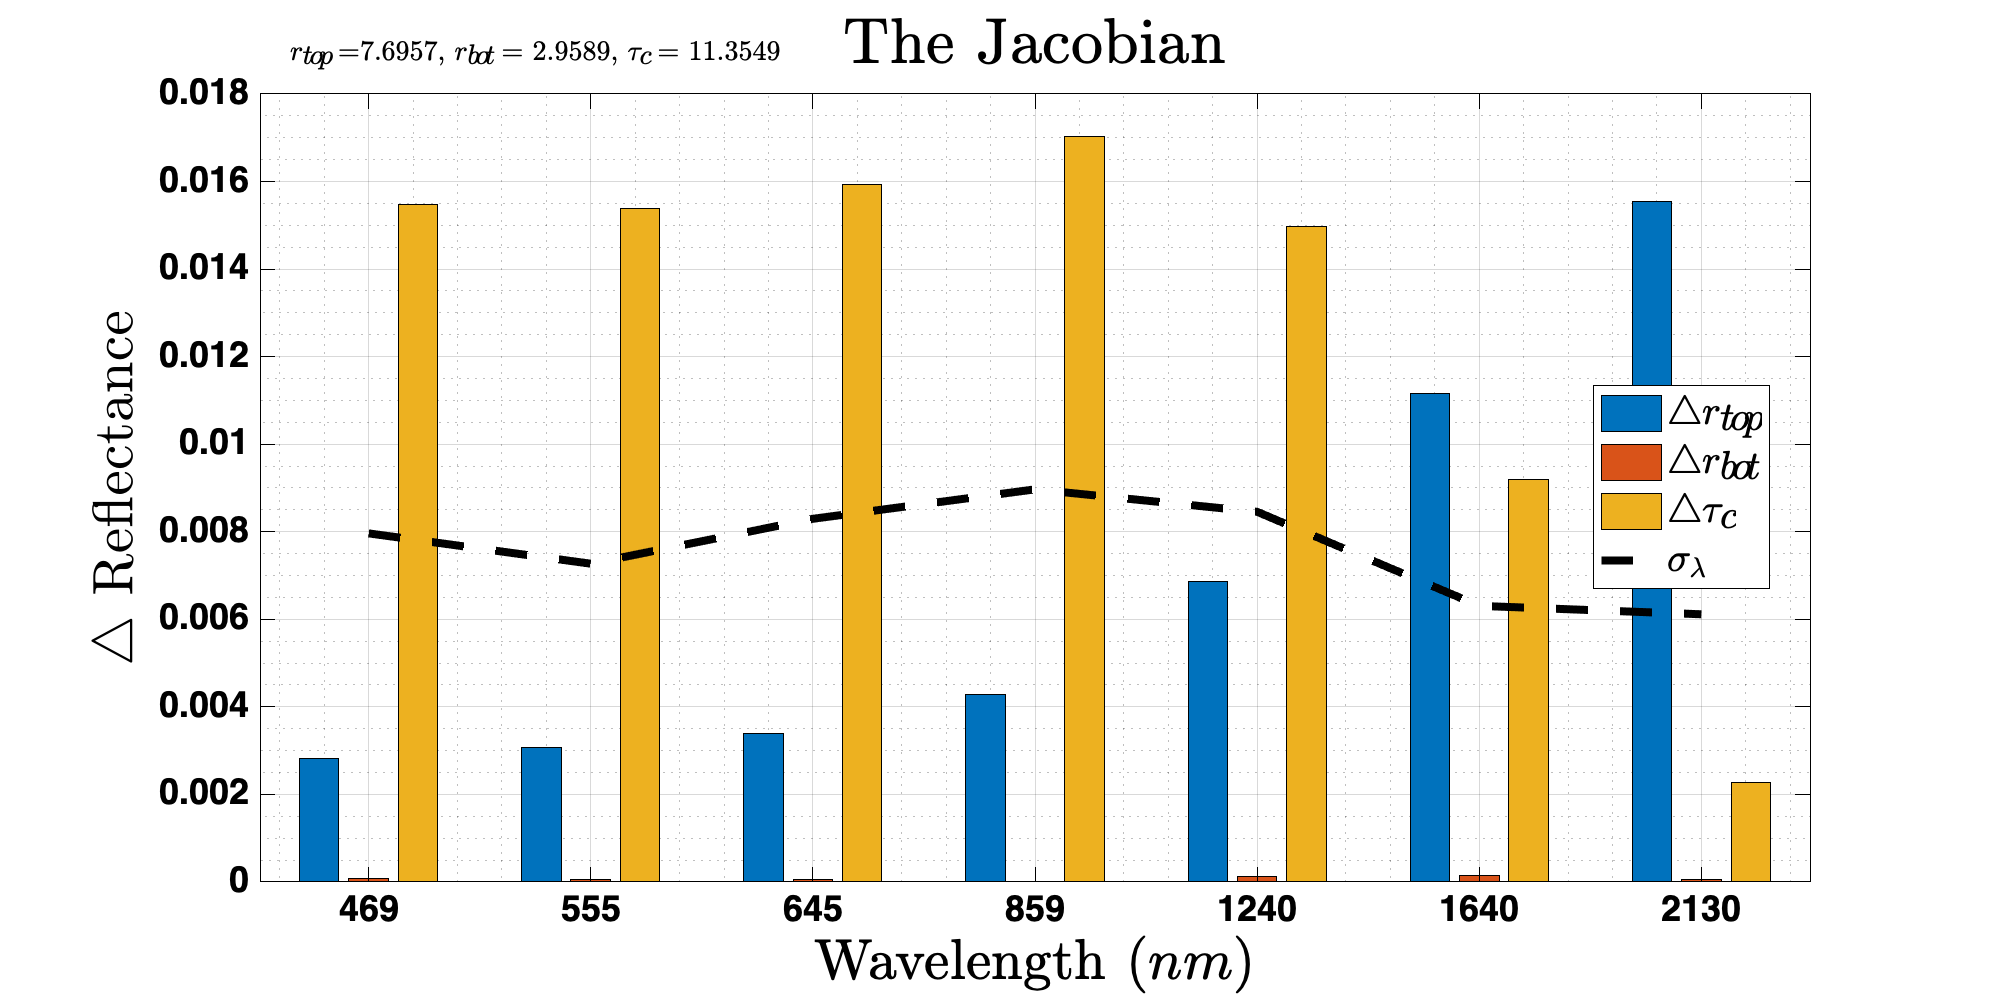

(iteration,pixel): (5,1)


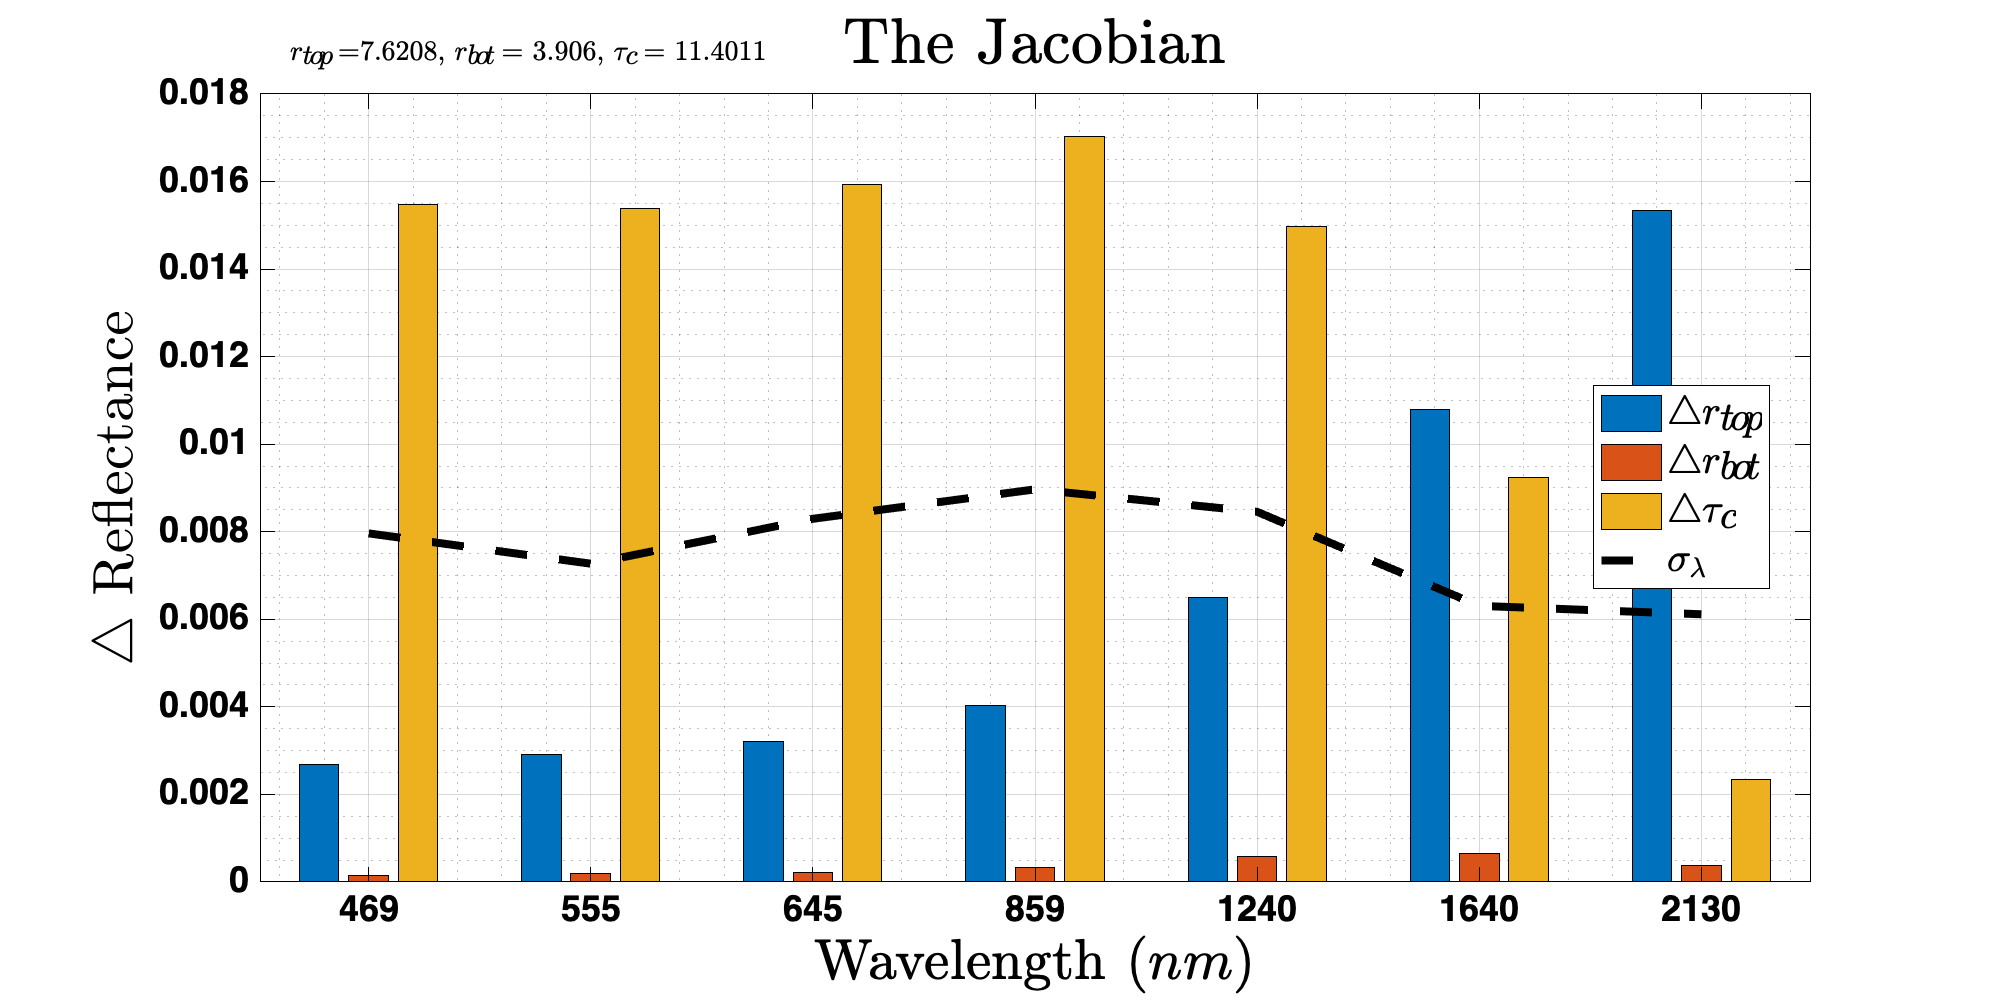

% Lets calculate the posterior pdf and the posterior covariance

tic
GN_outputs = calc_retrieval_gauss_newton_4modis(GN_inputs,modis,modisInputs,pixels2use);

toc

Elapsed time is 173.140890 seconds.


save([modisInputs.savedCalculations_folderName,'GN_inputs_outputs_',GN_inputs.model.profile.type,'_',date,'.mat'],"GN_outputs","GN_inputs");


## Plot the Retrieved Profile along with the VOCALS-REx in-situ profile and the MODIS retireval

% We want to plot the retrieved profile in optical depth space

GN_outputs.tau_vector = linspace(0,GN_outputs.retrieval(3,end),length(vocalsRex.altitude));

GN_outputs.re_profile = create_droplet_profile2([GN_outputs.retrieval(1,end), GN_outputs.retrieval(2,end)],...
    GN_outputs.tau_vector, 'optical_depth', GN_inputs.model.profile.type);



% Save this computation
save([modisInputs.savedCalculations_folderName,'GN_inputs_outputs_',GN_inputs.model.profile.type,'_',date,'.mat'],"GN_outputs","GN_inputs");


% ------------------------------------------------------------------
% ------------------ Compute optical depth -------------------------
% ------------------------------------------------------------------
% optical depth is defined to be 0 at cloud top and increasing towards
% cloud bottom
vector_length = length(vocalsRex.altitude);
tau = zeros(1,vector_length-1);
for ii = 1:vector_length-1
    
    % we have to convert Nc and re to have the same units as the alitude,
    % which is in meters
    re_meters = vocalsRex.re(vector_length-ii:vector_length)./1e6;                                   % meters
    total_Nc_meters = vocalsRex.total_Nc(vector_length-ii:vector_length).*1e6;                           % #/m^3
    altitude = vocalsRex.altitude(end) -  vocalsRex.altitude(vector_length-ii:vector_length);
    % we need to flip these vectors so we start integratin at the cloud
    % top!
    tau(ii) = 2*pi* trapz(fliplr(altitude), fliplr(re_meters.^2 .* total_Nc_meters));

end

% add a zero at the begining!
tau = [0,tau];


% ------------------------------------------------------------------
% ---------------- Compute Liquid Water Path -----------------------
% ------------------------------------------------------------------

LWP = trapz(vocalsRex.altitude, vocalsRex.lwc);                 % grams of water/m^2



% I want a subplot with the number concentration and altitude, and the
% effective radius with altitude
nice_blue = [0 0.4470 0.741];
nice_orange = [0.8500, 0.3250, 0.0980];


figure;

% Plot the vocals rex data as markers, but add a line through each to guide
% the eye
plot(fliplr(vocalsRex.re),tau,'Marker','.','MarkerSize',35, 'LineStyle','-', 'LineWidth',1);
set(gca,'YDir','reverse')
ylabel('$\tau$','interpreter','latex', 'FontSize', 35); 
xlabel('$r_{e}$ $$(\mu m)$$','Interpreter','latex')
title('Comparison of Gauss-Newton and MODIS retrieved $r_e$ with in-situ', 'Interpreter','latex')
grid on; grid minor; hold on; 

% Plot the Gauss-Newton Retreval

plot(GN_outputs.re_profile, GN_outputs.tau_vector, 'Color',curve_fit_color,'LineStyle',':', 'LineWidth',curve_fit_linewidth)

% Plot the modis droplet estimate as a constant vertical line
xl0 = xline(modis.cloud.effRadius17(vocalsRex.modisIndex_minDist),':',...
    ['MODIS $$r_{2.1} = $$',num2str(modis.cloud.effRadius17(vocalsRex.modisIndex_minDist)), '$$\mu m$$'],...
    'Fontsize',18, 'Interpreter','latex','LineWidth',2,'Color',nice_blue);
xl0.LabelVerticalAlignment = 'middle';
xl0.LabelHorizontalAlignment = 'right';

% Plot the MODIS optical depth estiamte as a constant horizontal line
yl0 = yline(modis.cloud.optThickness17(vocalsRex.modisIndex_minDist),':',...
    ['MODIS $$\tau_{2.1} = $$',num2str(modis.cloud.optThickness17(vocalsRex.modisIndex_minDist))],...
    'Fontsize',18, 'Interpreter','latex','LineWidth',2,'Color',nice_orange);
yl0.LabelVerticalAlignment = 'top';
yl0.LabelHorizontalAlignment = 'left';


% Plot the our GAuss-Newton retireval for optical depth as a constant horizontal line
yl1 = yline(GN_outputs.retrieval(3,end),':',...
    ['GN retrieved $$\tau_{c} = $$',num2str(round(GN_outputs.retrieval(3,end),2))],...
    'Fontsize',18, 'Interpreter','latex','LineWidth',2,'Color',curve_fit_color,'LabelVerticalAlignment','bottom',...
    'LabelHorizontalAlignment','center');

% Plot the z-space in meters on the right axis
yyaxis right
ylim([0, vocalsRex.altitude(end) - vocalsRex.altitude(1)])
set(gca,'YColor','black')
ylabel('Altitude within cloud $(m)$', 'Interpreter','latex','FontSize',30); 
yyaxis left

% Label cloud top and cloud bottom
% Create textbox
annotation('textbox',[0.029,0.865079365079366,0.051,0.077777777777778],...
    'String',{'Cloud','Top'},...
    'LineStyle','none',...
    'Interpreter','latex',...
    'FontSize',22,...
    'FitBoxToText','off');

% Create textbox
annotation('textbox',[0.029,0.096825396825397,0.051,0.077777777777778],...
    'String',{'Cloud','Bottom'},...
    'LineStyle','none',...
    'Interpreter','latex',...
    'FontSize',22,...
    'FitBoxToText','off');




% Let's compute the mean number concentration within this cloud and print
% it on our plot
mean_Nc = mean(vocalsRex.total_Nc);

dim = [.2 .5 .3 .3];
str = ['$$< N_c > = \;$$',num2str(round(mean_Nc)),' $$cm^{-3}$$',newline,'$$LWP = $$',num2str(round(LWP,1)),' $$g/m^{2}$$'];
annotation('textbox',dim,'String',str,'FitBoxToText','on','Interpreter','latex','FontSize',18,'FontWeight','bold');

% set figure size
set(gcf,'Position',[0 0 1300 730])

% Create a Legend with only the two black curves
legend('Vocals Rex In-situ Measurement', 'Retrieved Profile with first 7 channels of MODIS', 'Interpreter','latex', 'Location','best')

## Plot Gauss-Newton Iterative Progress

% Plot each pixel

for ii = 1:length(pixels2use.res1km.linearIndex)

    f = figure; subplot(1,2,1)
    plot(GN_outputs.rms_residual(:,ii),'.-', 'LineWidth',2);
    grid on; grid minor;
    title(['Pixel ',num2str(ii)], 'Interpreter','latex')
    xlabel('Iteration', 'Interpreter','latex')
    ylabel('RMS Residual', 'Interpreter','latex')
    subplot(1,2,2)
    plot(GN_outputs.retrieval(1,:,ii)','.-', 'LineWidth',2);
    hold on; grid on; grid minor
    plot(GN_outputs.retrieval(2,:,ii)','.-', 'LineWidth',2);
    xlabel('Iteration', 'Interpreter','latex')
    ylabel('$r_e$ ($\mu m$)', 'Interpreter','latex')
    yyaxis right
    plot(GN_outputs.retrieval(3,:,ii)','.-', 'LineWidth',2);
    legend('$r_{top}$', '$r_{bot}$','$\tau_c$','Location','best', 'Interpreter','latex')
    yline(modis.cloud.optThickness17(pixels2use.res1km.linearIndex(ii)), 'k:','TBLUT $\tau_c$','linewidth',2, 'Interpreter','latex')
    ylabel('$\tau_c$', 'Interpreter','latex')
    yyaxis left
    yline(modis.cloud.effRadius17(pixels2use.res1km.linearIndex(ii)), 'k--','TBLUT $r_e$', 'linewidth',2, 'Interpreter','latex')
    set(f,"Position", [0 0 1000 400])

end
% Plot the in-situ measured droplet profile along with the retrieved
% droplet profile

% index where Nc is constant
index = vocalsRex.time>6240 & vocalsRex.time<=6278;

% index covereing all Nc>0
index = vocalsRex.time>6227 & vocalsRex.time<=6278;

% Using a more selective index
index = [vocalsRex.time>= 6241 & vocalsRex.time<=6249, vocalsRex.time>= 6237 & vocalsRex.time<=6242,...
    vocalsRex.time>= 6237 & vocalsRex.time<=6242, vocalsRex.time>= 6237 & vocalsRex.time<=6242];

index = [vocalsRex.time>= 6237 & vocalsRex.time<=6243, vocalsRex.time>= 6237 & vocalsRex.time<=6242,...
    vocalsRex.time>= 6237 & vocalsRex.time<=6242, vocalsRex.time>= 6237 & vocalsRex.time<=6242];


% Lets create the droplet profile
% Set up a few constants for the water cloud
H = 0.04;                                % km - geometric thickness of cloud
n_layers = 10;                          % number of layers to model within cloud
z0 = 0.935;                                 % km - base height of cloud
indVar = 'altitude';                    % string that tells the code which independent variable we used
profile_type = GN_inputs.model.profile.type; % type of water droplet profile

for ii = 1:length(pixels2use.res1km.linearIndex)
    
    vocalsRex_altitude = vocalsRex.altitude(index(:,ii));
    z = linspace(vocalsRex_altitude(1), vocalsRex_altitude(end),n_layers)./1e3;        % km - altitude above ground vector

    re = create_droplet_profile2([GN_outputs.retrieval(1,end,ii), GN_outputs.retrieval(2,end,ii)], z, indVar, profile_type);     % microns - effective radius vector
    % For many situations the Number conentration is constant within the cloud
    % For this data set, that occurs aroudn time = 6240 seconds,
    % The last measurement occurs at time = 6278 indicating
    % the end of the cloud.


    f = figure; plot(vocalsRex.re(index(:,ii)), vocalsRex.altitude(index(:,ii)))
    hold on; grid on; grid minor
    plot(re, z*1e3, '--')
    xline(modis.cloud.effRadius17(pixels2use.res1km.linearIndex(ii)),'k:','TBLUT $r_e$',...
        'LabelVerticalAlignment','bottom','FontSize',15, 'Linewidth',2,'interpreter','latex')
    legend('VOCALS-REx', 'Retrieved','Location','best','Interpreter','latex')
    title('Comparison between Retrieved and In-Situ $r_e$', 'Interpreter','latex')
    xlabel('Effective Radius ($\mu m$)','Interpreter','latex')
    ylabel('Altitude ($m$)','Interpreter','latex')
    dim = [.76 0.1 .3 .3];
    str = ['$\tau_c = $ ',num2str(round(GN_outputs.retrieval(3,end,ii),1)),newline,'$r_e \propto \tau$'];
    annotation('textbox',dim,'String',str,'FitBoxToText','on','Color','k',...
        'FontWeight','bold','FontSize',24, 'EdgeColor','w','Interpreter','latex');
    set(f,"Position", [0 0 1000, 400])

end

## Compare 3 different profile assumptions on the same curve



index = [vocalsRex.time>= 6237 & vocalsRex.time<=6243, vocalsRex.time>= 6237 & vocalsRex.time<=6242,...
    vocalsRex.time>= 6237 & vocalsRex.time<=6242, vocalsRex.time>= 6237 & vocalsRex.time<=6242];


% Lets create the droplet profile
% Set up a few constants for the water cloud
n_layers = 10;                          % number of layers to model within cloud
indVar = 'altitude';                    % string that tells the code which independent variable we used


for ii = 1:length(pixels2use.res1km.linearIndex)
    
    vocalsRex_altitude = vocalsRex.altitude(index(:,ii));
    z = linspace(vocalsRex_altitude(1), vocalsRex_altitude(end),n_layers)./1e3;        % km - altitude above ground vector


    load('GN_inputs_outputs_adiabatic_30-Jun-2022.mat')
    profile_type = GN_inputs.model.profile.type; % type of water droplet profile
    re_1 = create_droplet_profile2([GN_outputs.retrieval(1,end,ii), GN_outputs.retrieval(2,end,ii)], z, indVar, profile_type);     % microns - effective radius vector

    load('GN_inputs_outputs_sub-adiabatic_30-Jun-2022.mat')
    profile_type = GN_inputs.model.profile.type; % type of water droplet profile
    re_2 = create_droplet_profile2([GN_outputs.retrieval(1,end,ii), GN_outputs.retrieval(2,end,ii)], z, indVar, profile_type);     % microns - effective radius vector

    load('GN_inputs_outputs_linear-with-tau_30-Jun-2022.mat')
    profile_type = GN_inputs.model.profile.type; % type of water droplet profile
    re_3 = create_droplet_profile2([GN_outputs.retrieval(1,end,ii), GN_outputs.retrieval(2,end,ii)], z, indVar, profile_type);     % microns - effective radius vector


    % For many situations the Number conentration is constant within the cloud
    % For this data set, that occurs aroudn time = 6240 seconds,
    % The last measurement occurs at time = 6278 indicating
    % the end of the cloud.


    f = figure; plot(vocalsRex.re(index(:,ii)), vocalsRex.altitude(index(:,ii)))
    hold on; grid on; grid minor
    plot(re_1, z*1e3, '--'); plot(re_2, z*1e3, '--'); plot(re_3, z*1e3, '--')
    xline(modis.cloud.effRadius17(pixels2use.res1km.linearIndex(ii)),'k:','TBLUT $r_e$',...
        'LabelVerticalAlignment','bottom','FontSize',15, 'Linewidth',2,'interpreter','latex')
    legend('VOCALS-REx', 'Adiabatic', '$r_e \propto z$', '$r_e \propto \tau$','Location','best','Interpreter','latex')
    title('Comparison between Retrieved and In-Situ $r_e$', 'Interpreter','latex')
    xlabel('Effective Radius ($\mu m$)','Interpreter','latex')
    ylabel('Altitude ($m$)','Interpreter','latex')
    dim = [.76 0.1 .3 .3];
    str = ['$\tau_c = $ ',num2str(round(GN_outputs.retrieval(3,end,ii),1))];
    annotation('textbox',dim,'String',str,'FitBoxToText','on','Color','k',...
        'FontWeight','bold','FontSize',24, 'EdgeColor','w','Interpreter','latex');
    set(f,"Position", [0 0 1000, 400])

end

## Calculate the Posterior Distribution

% here is where I will talk about averaging kernels

## Calculate Information Content

% here is where I will talk about averaging kernels

## Calculate Degrees of Freedom for Signal

% here is where I will talk about averaging kernels

## Optimize Channel Selection Based on Information Content

% here is where I will talk about averaging kernels

## Optimize Channel Selection Based on Degrees of Freedom for Signal

% here is where I will talk about averaging kernels

## Calculate Averaging Kernels

% here is where I will talk about averaging kernels

## Create Input Structure for Bayes Functions

% create the input structure for the bayesian inverse functions
% by default, the code assumes both the model and measurement prior are
% gaussian, and that every model parameter and measurement is independent
